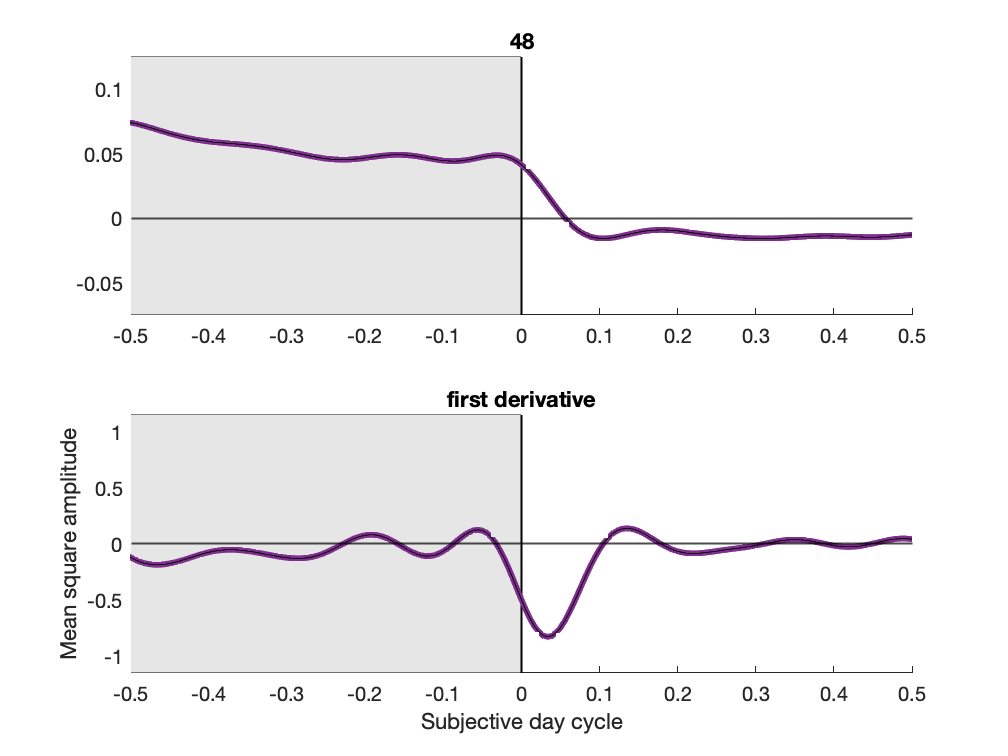


clrs = k_colormefriendly;

    

    for j = 12%:length(dark)

  figure(j); clf; hold on; 

     ld(j,:) = dark(j).ld;

    ax(1) = subplot(211); title(num2str(ld(j))); hold on;
        ylim([-.075 .125]);
       % ylim([.4 .6]);
        xlim([-0.5 0.5]);
        a = ylim; fill([-ld(j) -ld(j) 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
        yline(0, 'k-', 'LineWidth',1);
        plot([0,0], ylim, 'k-', 'LineWidth', 1);
        plot(dark(j).exp.hourtim-ld(j), dark(j).exp.meanofexperimentmeans-mean(dark(j).exp.meanofexperimentmeans), 'LineWidth', 3,'Color', clrs(j,:));
        plot(dark(j).exp.hourtim-ld(j), dark(j).exp.meanofexperimentmeans-mean(dark(j).exp.meanofexperimentmeans), 'LineWidth', .5,'Color', 'k');
        
       

    ax(2) = subplot(212); title('first derivative'); hold on;
        
        darkdy = gradient(dark(j).exp.meanofexperimentmeans)./gradient(dark(j).exp.hourtim);

          ylim([-1.15 1.15]);xlim([-0.5 0.5]);
          a = ylim; fill([-ld(j) -ld(j), 0 0 ], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
          yline(0, 'k-', 'LineWidth',1);
          plot([0,0], ylim, 'k-', 'LineWidth', 1);
          plot(dark(j).exp.hourtim-ld(j), darkdy,'LineWidth', 3,'Color', clrs(j,:));
          plot(dark(j).exp.hourtim-ld(j), darkdy,'LineWidth', .5,'Color', 'k');
          

    linkaxes(ax,'x');    
    end
       
  
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

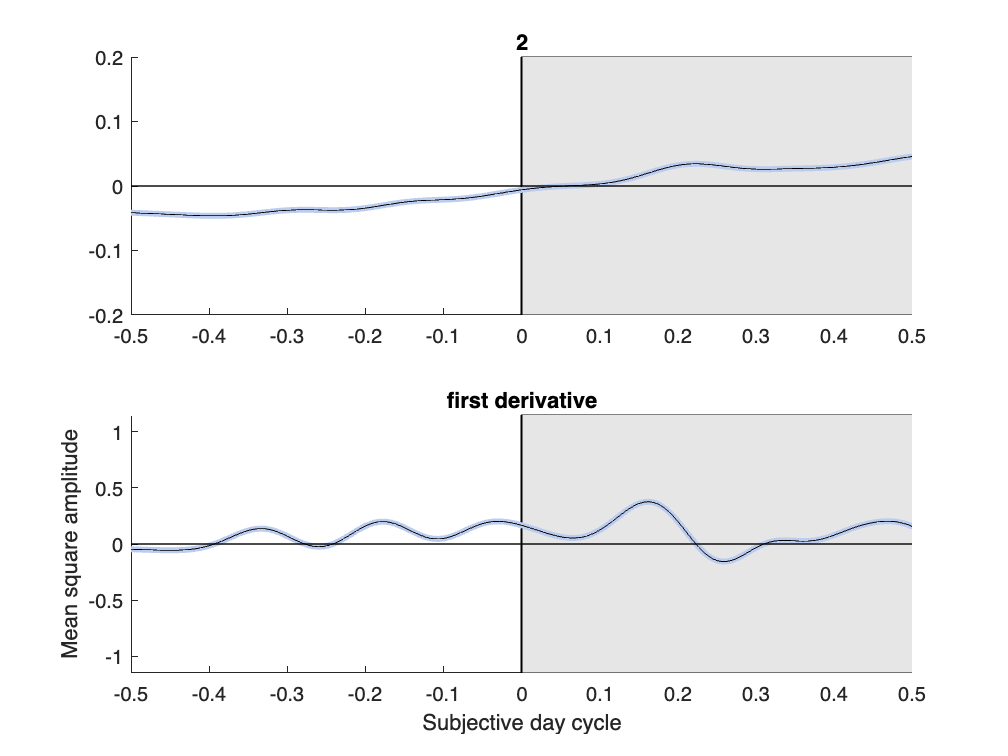

clrs = k_colormefriendly;

    

    for j = 1%:length(light)

  figure(j); clf; hold on; 

     ld(j,:) = light(j).ld;

    ax(1) = subplot(211); title(num2str(ld(j))); hold on;
       % ylim([-.075 .125]);
        ylim([-.2 .2]);
        xlim([-0.5 0.5]);

        a = ylim; fill([0 0 ld(j) ld(j)], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

        yline(0, 'k-', 'LineWidth',1);
        plot([0,0], ylim, 'k-', 'LineWidth', 1);
        plot(light(j).exp.hourtim-ld(j), light(j).exp.meanofexperimentmeans-mean(light(j).exp.meanofexperimentmeans), 'LineWidth', 3,'Color', clrs(j,:));
        plot(light(j).exp.hourtim-ld(j), light(j).exp.meanofexperimentmeans-mean(light(j).exp.meanofexperimentmeans), 'LineWidth', .5,'Color', 'k');
        
       

    ax(2) = subplot(212); title('first derivative'); hold on;
        
        lightdy = gradient(light(j).exp.meanofexperimentmeans)./gradient(light(j).exp.hourtim);

          ylim([-1.15 1.15]);xlim([-0.5 0.5]);
          a = ylim; fill([0 0 ld(j) ld(j)], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
          yline(0, 'k-', 'LineWidth',1);
          plot([0,0], ylim, 'k-', 'LineWidth', 1);
          plot(light(j).exp.hourtim-ld(j), lightdy,'LineWidth', 3,'Color', clrs(j,:));
          plot(light(j).exp.hourtim-ld(j), lightdy,'LineWidth', .5,'Color', 'k');
          

    linkaxes(ax,'x');    
    end
       
  
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

# multi

dark to light

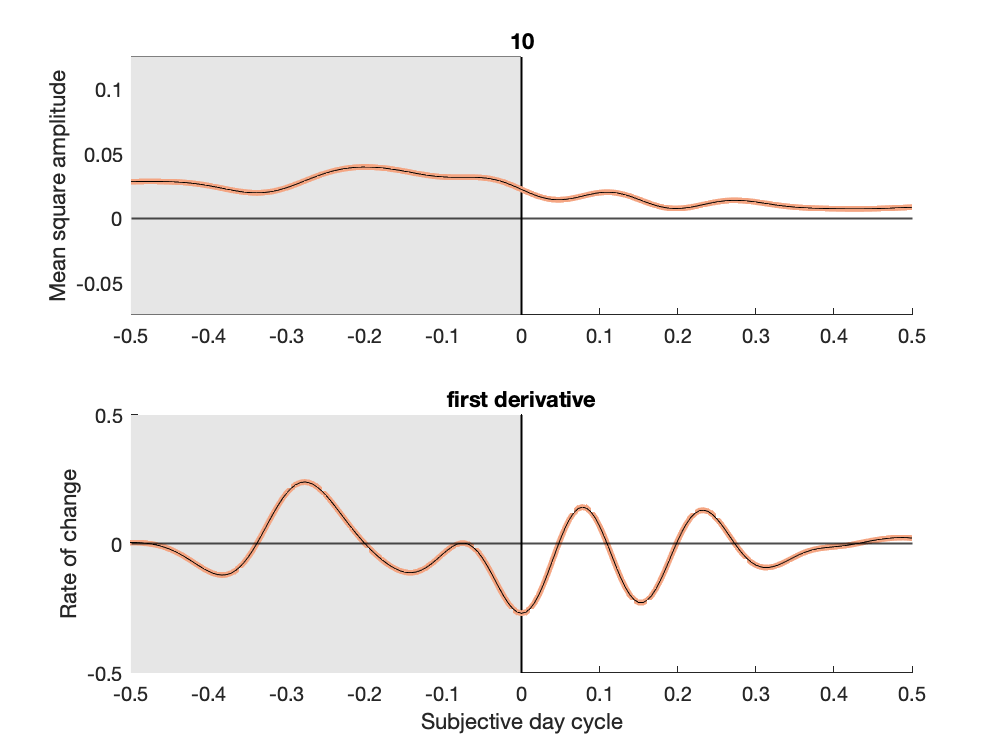

clrs = k_colormefriendly;

    

    for j = 7%:length(dark)

  figure(j); clf; hold on; 

     ld(j,:) = dark(j).ld;

    ax(1) = subplot(211); title(num2str(ld(j))); hold on;
        ylim([-.075 .125]);
       % ylim([.4 .6]);
        xlim([-0.5 0.5]);
        a = ylim; fill([-ld(j) -ld(j) 0 0], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
        yline(0, 'k-', 'LineWidth',1);
        plot([0,0], ylim, 'k-', 'LineWidth', 1);
        plot(darkmulti(j).exp.hourtim-ld(j), darkmulti(j).exp.meanofexperimentmeans-mean(darkmulti(j).exp.meanofexperimentmeans), 'LineWidth', 3,'Color', clrs(j,:));
        plot(darkmulti(j).exp.hourtim-ld(j), darkmulti(j).exp.meanofexperimentmeans-mean(darkmulti(j).exp.meanofexperimentmeans), 'LineWidth', .5,'Color', 'k');
        
        ylabel('Mean square amplitude');

    ax(2) = subplot(212); title('first derivative'); hold on;
        
        darkdy = gradient(darkmulti(j).exp.meanofexperimentmeans)./gradient(darkmulti(j).exp.hourtim);

          ylim([-1.15 1.15]);xlim([-0.5 0.5]);
          a = ylim; fill([-ld(j) -ld(j), 0 0 ], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
          yline(0, 'k-', 'LineWidth',1);
          plot([0,0], ylim, 'k-', 'LineWidth', 1);
          plot(darkmulti(j).exp.hourtim-ld(j), darkdy,'LineWidth', 3,'Color', clrs(j,:));
          plot(darkmulti(j).exp.hourtim-ld(j), darkdy,'LineWidth', .5,'Color', 'k');
          
        ylim([-.5 .5]);
    linkaxes(ax,'x');    
    end
       
   ylabel('Rate of change');
   
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');

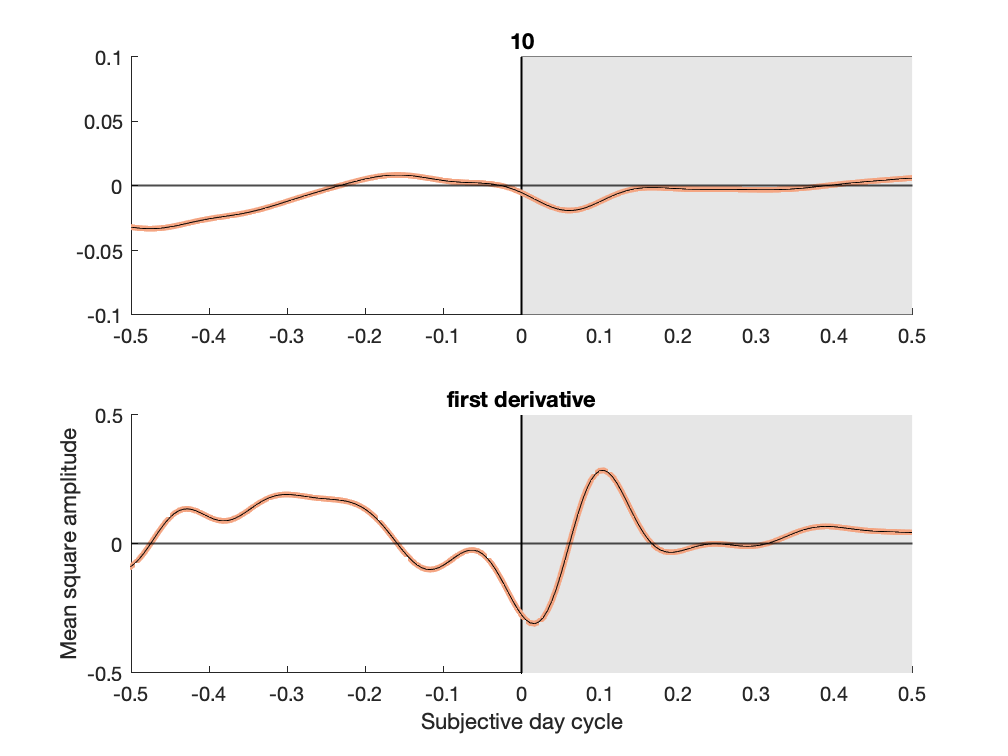

clrs = k_colormefriendly;

    

    for j = 7%:length(light)

  figure(j); clf; hold on; 

     ld(j,:) = light(j).ld;

    ax(1) = subplot(211); title(num2str(ld(j))); hold on;
        ylim([-.075 .125]);
        ylim([-.1 .1]);
        xlim([-0.5 0.5]);

        a = ylim; fill([0 0 ld(j) ld(j)], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');

        yline(0, 'k-', 'LineWidth',1);
        plot([0,0], ylim, 'k-', 'LineWidth', 1);
        plot(lightmulti(j).exp.hourtim-ld(j), lightmulti(j).exp.meanofexperimentmeans-mean(lightmulti(j).exp.meanofexperimentmeans), 'LineWidth', 3,'Color', clrs(j,:));
        plot(lightmulti(j).exp.hourtim-ld(j), lightmulti(j).exp.meanofexperimentmeans-mean(lightmulti(j).exp.meanofexperimentmeans), 'LineWidth', .5,'Color', 'k');
        
       

    ax(2) = subplot(212); title('first derivative'); hold on;
         
        lightdy = gradient(lightmulti(j).exp.meanofexperimentmeans)./gradient(lightmulti(j).exp.hourtim);

          ylim([-1.15 1.15]);xlim([-0.5 0.5]);
          a = ylim; fill([0 0 ld(j) ld(j)], [a(1) a(2) a(2) a(1)], [0.9, 0.9, 0.9], 'HandleVisibility','off');
          yline(0, 'k-', 'LineWidth',1);
          plot([0,0], ylim, 'k-', 'LineWidth', 1);
          plot(lightmulti(j).exp.hourtim-ld(j), lightdy,'LineWidth', 3,'Color', clrs(j,:));
          plot(lightmulti(j).exp.hourtim-ld(j), lightdy,'LineWidth', .5,'Color', 'k');
          ylim([-.5 .5]);

    linkaxes(ax,'x');    
    end
       
  
    ylabel('Mean square amplitude');
    xlabel('Subjective day cycle');
    set(gcf, 'Renderer', 'painters');